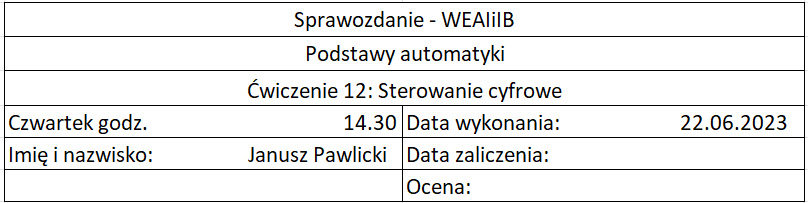

## 1. Cel ćwiczenia

Celem ćwiczenia jest zapoznanie się z budową i działaniem układu regulacji składającego się z ciągłego obiektu regulacji oraz regulatora cyfrowego (dyskretnego). Z taką sytuacją mamy do czynienia w każdej sytuacji, gdy regulator jest zrealizowany na jakiejkolwiek platformie cyfrowej (komputer, sterownik PLC, mikrokontroler, Raspberry Pi, etc). Pomiędzy układami ciągłymi i dyskretnymi występują zarówno analogie, jak i różnice. Podstawowym parametrem układu dyskretnego jest okres próbkowania, określający, jak często odczytywana jest wielkość regulowana z obiektu i wystawiany sygnał sterujący z regulatora na obiekt. Odpowiednikiem transmitancji operatorowej G(s) jest transmitancja dyskretna G(z). 

## 2. Wstęp

**Układ dyskretny**, **układ dyskretny w czasie**, **układ skwantowany w czasie**, **układ impulsowy** – w teorii sterowania, w odróżnieniu od układów ciągłych, określa się, że układ jest dyskretny, jeżeli przynajmniej jeden jego sygnał ma charakter dyskretny, tzn. przyjmuje tylko określone wartości dla określonych argumentów (zob. sygnał dyskretny, sygnał cyfrowy). Układy przejawiające w swym zachowaniu zarówno cechy układów ciągłych, jak i dyskretnych, nazywane są układami hybrydowymi.

## 3. Przebieg laboratorium 

### 3.1 Zadanie 1

Zbadanie wpływu wartości okresu próbkowania na stabilność układu regulacji cyfrowej.

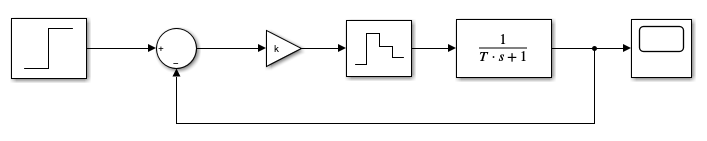

Rys. 1 Model w simulinku

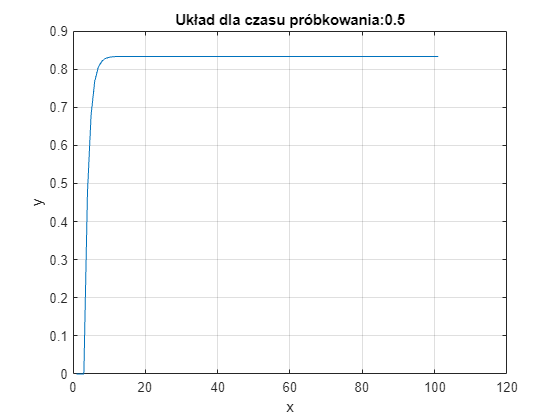

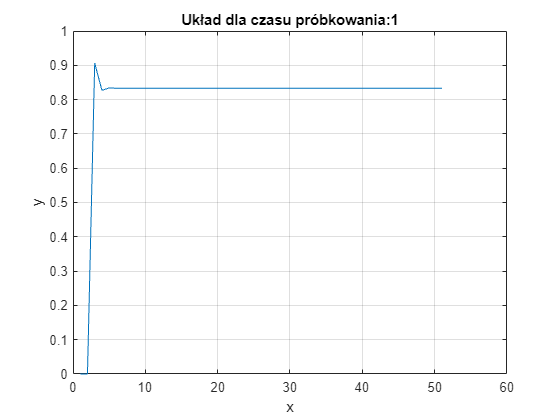

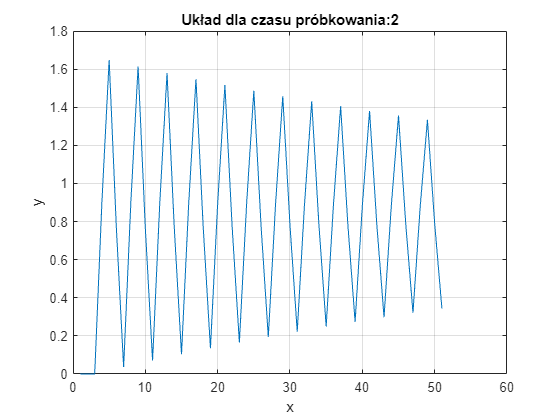

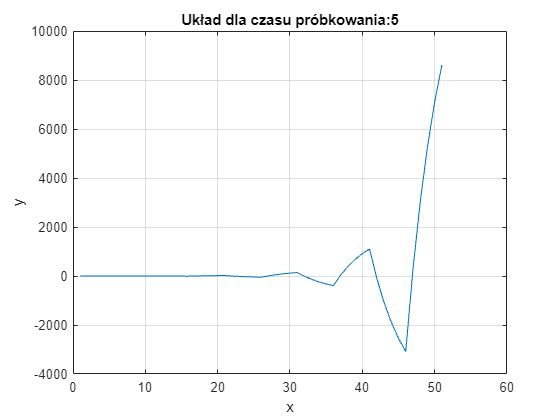

clear

k = 5;
T = 5;
TP = [0.5, 1, 2, 5]; % Czas próbkowania
% Końcowy czas symulacji = 50 sekund

for i = 1:4
    Tp = TP(i);
    clear sim
    sim("uklad1.slx");
    figure;
    plot(ans.y.signals.values);
    grid on
    title(strcat('Układ dla czasu próbkowania: ', num2str(Tp)))
    xlabel('x')
    ylabel('y')
end

### 3.2 Zadanie 2

Obserwacja sposobu przejścia sygnału cyfrowego przez obiekt wysokiego rzędu.

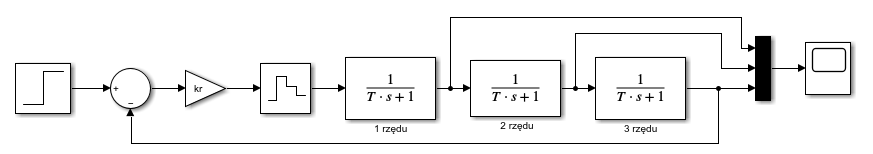

Rys. 2 Model w simulinku

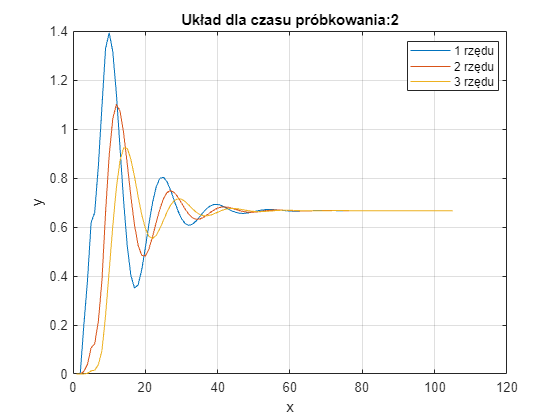

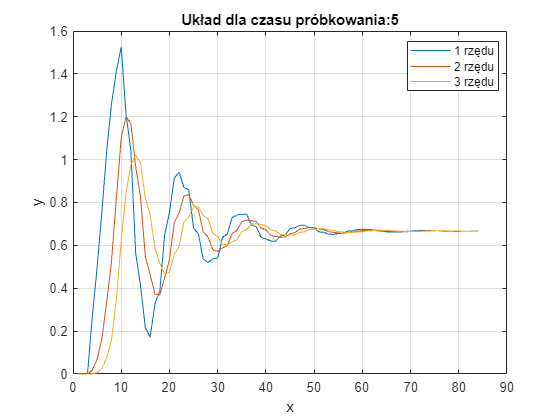

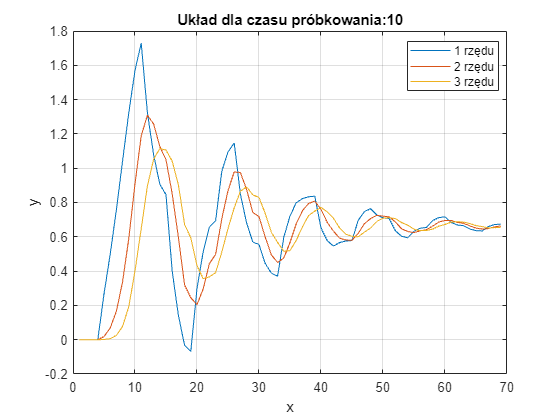

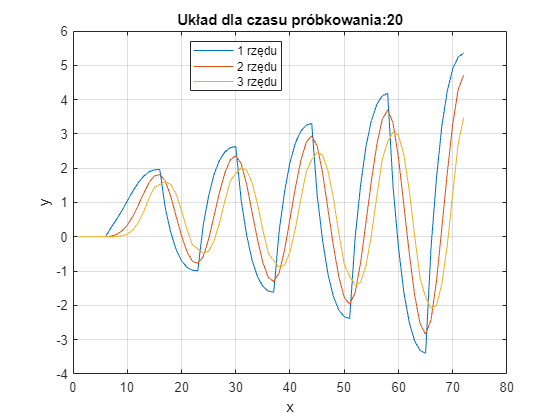

clear

kr = 2;
T = 5; 
TP = [2, 5, 10, 20]; % Czas próbkowania
% Końcowy czas symulacji = 200 sekund

for i = 1:4
    Tp = TP(i);
    clear sim
    sim("uklad2.slx");
    figure;
    plot(ans.y.signals.values);
    grid on
    title(strcat('Układ dla czasu próbkowania: ', num2str(Tp)))
    xlabel('x')
    ylabel('y')
    legend('1 rzędu', '2 rzędu', '3 rzędu')
    legend('Location', 'best')
end

### 3.3 Zadanie 3

Zbadanie działania zamkniętego układu regulacji cyfrowej z dyskretnym regulatorem PID.

Rys. 3 Obiekt regulacji

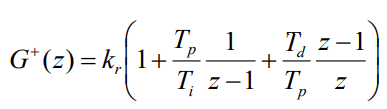

Rys. 4 Dyskretny regulator PID

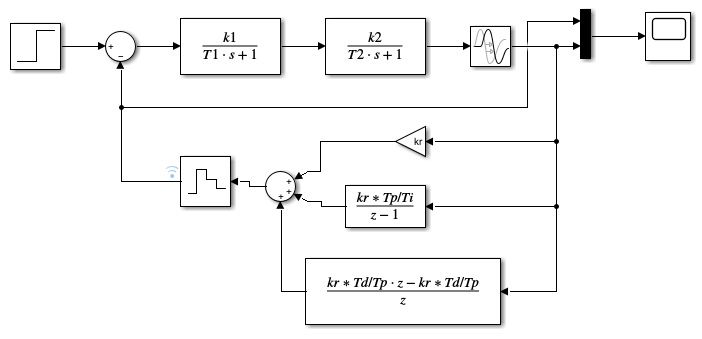

Rys. 5 Model w simulinku

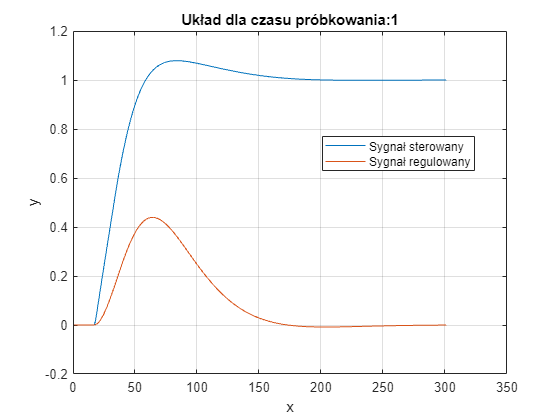

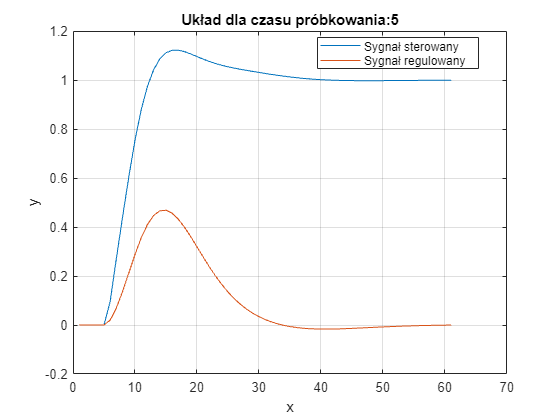

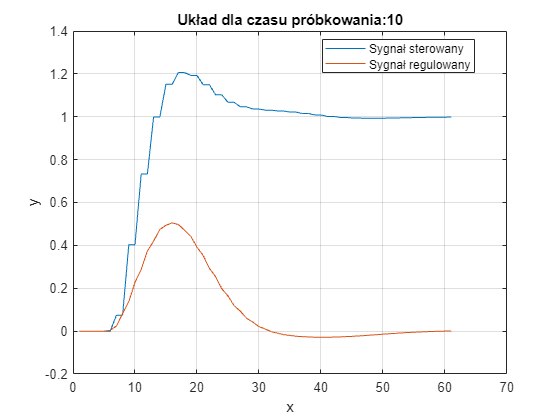

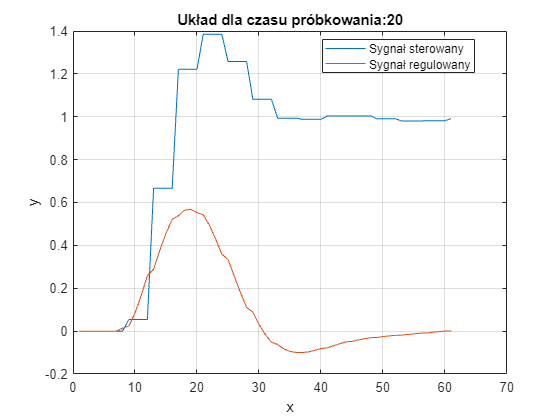

clear 

k1 = 1.08;
k2 = 1;
T1 = 14.0786;
T2 = 39.0451;
kr = 1.5;
Ti = 45;
Td = 11;
TP = [1, 5, 10, 20]; % Czas próbkowania
tau = -15.1975;
% czas końcowy symulacji równy 300 sekund

for i = 1:4
    Tp = TP(i);
    clear sim
    sim("uklad3.slx");
    figure;
    plot(ans.y.signals.values);
    grid on
    title(strcat('Układ dla czasu próbkowania: ', num2str(Tp)))
    xlabel('x')
    ylabel('y')
    legend('Sygnał sterowany', 'Sygnał regulowany')
    legend('Location', 'best')
end

## 4. Wnioski

Zad 1:

- Destabilizacje układu powoduje ekstrapolator, ponieważ ekstrapolator używa przybliżeń co powoduje błędy numeryczne, przy użyciu jej wiele razy błędy zaczynają się kumulować co prowadzi do stebilizacji.

- Zwiększenie czasu próbkowania zmniejsza dokładność wykresu.

Zad 2:

- .Zwięlkszenie rzędu obiektu zmniejszyło oscylacje.

Zad 3:

- Na wykresie widać zmiany związane z czasem próbkowania.